# **Basics of programming**

# Write a welcome message

quote="Hello world, ready to learn Matlab?";
fprintf(quote)

Hello world, ready to learn Matlab?

# Type of variables used in Matlab

## *1. Numbers*

**1. double** (default numeric type): anything between -Inf to +Inf

x = 3.14  % double

x = 3.1400

**2. single**: anything between 0 and +Inf

y = single(3.14)

y = single
3.1400

**3. integer types** (signed=positive and negative, and unsigned=0 and positive): 

- `int8`, `int16`, `int32`, `int64`

- `uint8`, `uint16`, `uint32`, `uint64`

z = uint8(3.14)

z = uint8
3

## **Question: When should you use double/single/integrer? and why?**

## *2. Logical*

**logical values** (true/false)

a=logical(1)

a = logical
   1


a=true

a = logical
   1


b=logical(0)

b = logical
   0


b=false

b = logical
   0


## ***3. Text ***

You can use either a character or string array to store text. 

String arrays are more recent (introduced in 2016 version) but more heavy

**string array**

quote="Hello world, ready to learn Matlab?"

quote = "Hello world, ready to learn Matlab?"

size(quote)

ans =      1     1


**character array**

quote='Hello world, ready to learn Matlab?';
size(quote)

ans =      1    35


# How to organize data in Matlab

# *1. numerical data only -> use of numerical array*

## **1.1 generate a matrix**

MyMatrix= [1	5	1	3
2	4	2	2
1	3	3	1
2	6	3	5
5	7	2	6
6	8	2	7];

MyMatrix

MyMatrix =      1     5     1     3
     2     4     2     2
     1     3     3     1
     2     6     3     5
     5     7     2     6
     6     8     2     7


**Identify the dimension and properties of my matrix**

whos MyMatrix

  Name          Size            Bytes  Class     Attributes

  MyMatrix      6x4               192  double              



size(MyMatrix)

**Impact of the numeric type on data size**

If data is single instead of double

singleMyMatrix=single(MyMatrix);
whos singleMyMatrix

  Name                Size            Bytes  Class     Attributes

  singleMyMatrix      6x4                96  single              



If data is 8bit instead of double

uint8MyMatrix=uint8(MyMatrix);
whos uint8MyMatrix

  Name               Size            Bytes  Class    Attributes

  uint8MyMatrix      6x4                24  uint8              



## **1.2. plot your matrix**

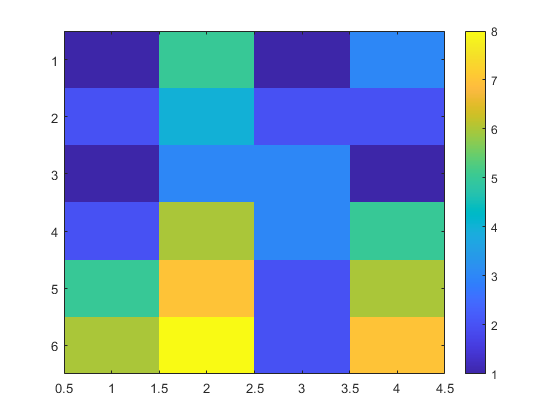

figure, imagesc(MyMatrix), colorbar

you can change the axis of your colorbar, same way as adjusting the brightness/contrast values in imageJ

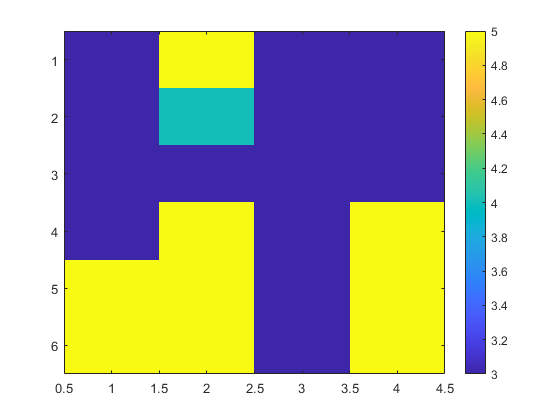

figure, imagesc(MyMatrix), colorbar, caxis([3 5])

You can change the colormap, same way as adjusting the LUT in imageJ-

More information is available here for the standard colormap in matlab [https://se.mathworks.com/help/matlab/ref/colormap.html](https://se.mathworks.com/help/matlab/ref/colormap.html) 

You can also generate your own colormap.

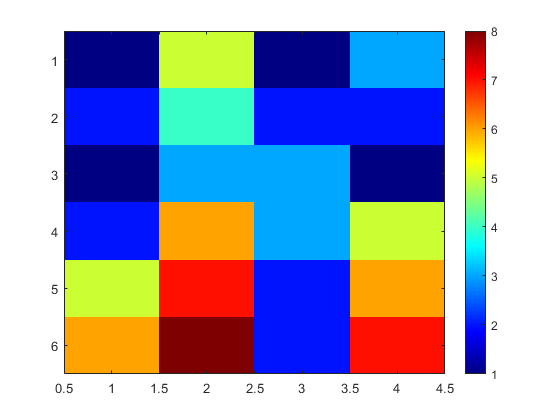

figure, imagesc(MyMatrix), colorbar, colormap(jet)

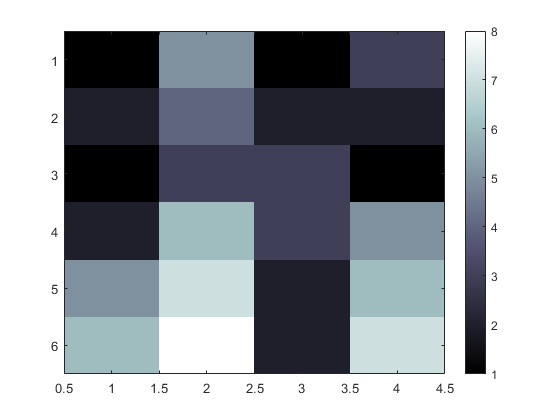

figure, imagesc(MyMatrix), colorbar, colormap(bone)

## 2. Working with real numeric data

### 2.1 Remember an image is a matrix of pixels containing intensity values.

Load an example image from Matlab

Image = imread("ngc6543a.jpg");

Get the infromation about that image

info = imfinfo("ngc6543a.jpg")

info = struct with fields:
           Filename: 'C:\Program Files\MATLAB\R2021a\toolbox\matlab\demos\ngc6543a.jpg'
        FileModDate: '01-Oct-1996 22:19:44'
           FileSize: 27387
             Format: 'jpg'
      FormatVersion: ''
              Width: 600
             Height: 650
           BitDepth: 24
          ColorType: 'truecolor'
    FormatSignature: ''
    NumberOfSamples: 3
       CodingMethod: 'Huffman'
      CodingProcess: 'Sequential'
            Comment: {'CREATOR: XV Version 3.00b  Rev: 6/15/94  Quality = 75, Smoothing = 0↵'}


whos Image

  Name         Size                 Bytes  Class    Attributes

  Image      650x600x3            1170000  uint8              



Color images (RGB) contains usually a 3rd dimension, where values 1 are R(ed), values 2 are G(green), values 3 are B(lue)

Image

Image = 650×600×3 uint8 array
Image(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0

### 2.2 Plot your image

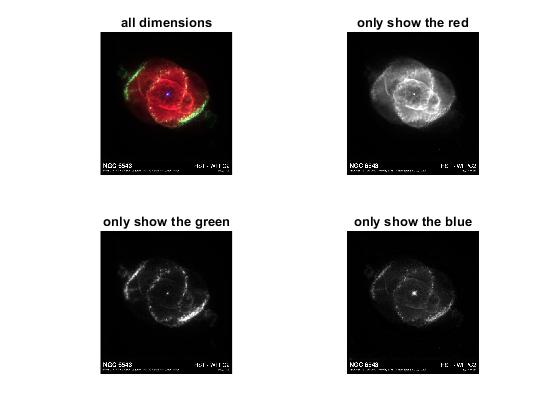

figure, 
subplot(2,2,1), imshow(Image), title('show all dimensions')
subplot(2,2,2), imshow(Image(:,:,1)), title('only show the red')
subplot(2,2,3), imshow(Image(:,:,2)), title('only show the green')
subplot(2,2,4), imshow(Image(:,:,3)), title('only show the blue')

Give more examples of how to plot certain data

# *2. mixed information (text, logical, numerical values)*

Multiple options are possible

- tables

- cell arrays

- structure arrays

# *2.1 Table*

Work like a spreadsheet with the following advantages: 

- named columns

- easy data manipulations

- column-oriented processing

- easy to import from excel/csv files

## Generate your own table

Load data available within Matlab and generate a table

load patients
T = table(Age,Height,Weight,Systolic,Diastolic, ...
          'RowNames',LastName);
T.Properties

ans =   TableProperties with properties:

             Description: ''
                UserData: []
          DimensionNames: {'Row'  'Variables'}
           VariableNames: {'Age'  'Height'  'Weight'  'Systolic'  'Diastolic'}
    VariableDescriptions: {}
           VariableUnits: {}
      VariableContinuity: []
                RowNames: {100×1 cell}
        CustomProperties: No custom properties are set.
      Use addprop and rmprop to modify CustomProperties.


display the whole table

T

T = 100×5 table
                Age    Height    Weight    Systolic    Diastolic
                ___    ______    ______    ________    _________

    Smith       38       71       176        124          93    
    Johnson     43       69       163        109          77    
    Williams    38       64       131        125          83    
    Jones       40       67       133        117          75    
    Brown       49       64       119        122          80    
    Davis       46       68       142        121          70    
    Miller      33       64       142        130          88    
    Wilson      40       68       180        115          82    
    Moore   

display only the rows with Smith and Brown

T(["Smith","Brown"],:)

ans = 2×5 table
             Age    Height    Weight    Systolic    Diastolic
             ___    ______    ______    ________    _________

    Smith    38       71       176        124          93    
    Brown    49       64       119        122          80    


display only the columns with Age and Height

T(:,["Age","Height"])

ans = 100×2 table
                Age    Height
                ___    ______

    Smith       38       71  
    Johnson     43       69  
    Williams    38       64  
    Jones       40       67  
    Brown       49       64  
    Davis       46       68  
    Miller      33       64  
    Wilson      40       68  
    Moore       28       68  
    Taylor      31       66  
    Anderson    45       68  
    Thomas      42       66  
    Jackson     25       71  
    White       39       72  
    Harris      36       65  
    Martin      48       71  


You can easily sort the rows of a table

sortedT = sortrows(T,"Age","ascend")

ans = 100×5 table
                 Age    Height    Weight    Systolic    Diastolic
                 ___    ______    ______    ________    _________

    Jackson      25       71       174        127          74    
    Hall         25       70       189        114          77    
    Young        25       63       114        125          76    
    Hill         25       64       138        115          80    
    James        25       66       186        125          75    
    Alexander    25       69       171        128          99    
    Garcia       27       69       131        123          79    
    Moore        28       68       183        115          78    
    Wal

## Load a table from an excel file

Use the Import Data tab to import data from exampleTable

%%

Use the names from column 1 as RowNames

cols = {'Age', 'Height'};
newTable = table(exampleTable.(cols{1}), exampleTable.(cols{2}), ...
    'VariableNames', cols, ...
    'RowNames', string(exampleTable.VarName1));
newTable

newTable = 100×2 table
                  Age    Height
                  ___    ______

    'Smith'       38       71  
    'Johnson'     43       69  
    'Williams'    38       64  
    'Jones'       40       67  
    'Brown'       49       64  
    'Davis'       46       68  
    'Miller'      33       64  
    'Wilson'      40       68  
    'Moore'       28       68  
    'Taylor'      31       66  
    'Anderson'    45       68  
    'Thomas'      42       66  
    'Jackson'     25       71  
    'White'       39       72  
    'Harris'      36       65  
    'Martin'      48       71  


# *2.2 Cell arrays*

Cell arrays are useful when your data just isn’t all one type or size and when you want to organize data of variable length and list of items in a dynamic way (if you do not know in advance how your data will look like)

They can easily be used for further calculation

**Generate your own cell array**

% Generate a cell array where each row = one survey respondent
MycellArray = {'Alice',   [5 4 4],    "Loved it";
    'Bob',     [3 2],      "";
    'Charlie', [5 5 5 5],  "Amazing!"};
MycellArray

MycellArray = 3×3 cell array
    {'Alice'  }    {[  5 4 4]}    {["Loved it"]}
    {'Bob'    }    {[    3 2]}    {[""        ]}
    {'Charlie'}    {[5 5 5 5]}    {["Amazing!"]}


whos MycellArray

  Name             Size            Bytes  Class    Attributes

  MycellArray      3x3              1520  cell               



**Note** 

- you can have different number of values in each array of the cell array

- you do not have row and column names in contrast to table

- you can also save  astructure array within your array, which allows to store different information

You can generate a table from a cell array

T = cell2table(MycellArray, ...
    'VariableNames', {'Name', 'Ratings', 'Comments'});

but cell arrays are more practical for functions and dynamic access, especially using cellfun which apply functions to each cell in cell array [https://se.mathworks.com/help/matlab/ref/cellfun.html?searchHighlight=cellfun&s_tid=srchtitle_support_results_1_cellfun](https://se.mathworks.com/help/matlab/ref/cellfun.html?searchHighlight=cellfun&s_tid=srchtitle_support_results_1_cellfun) 

**Example**

1. Find numeric values

cellfun(@(x) isnumeric(x), MycellArray)

ans = 3×3 logical array
   0   1   0
   0   1   0
   0   1   0


2. calculate mean of the column 2 of MycellArray = MycellArray(:,2)

cellfun(@(x) mean(x), MycellArray(:,2))

ans =     4.3333
    2.5000
    5.0000


# *2.3 Structure arrays*

Very useful to organize data by field names instead of columns or row positions

**Create your structure array**

student.Name = 'Alice';
student.Score = [92 88 94];
student.Passed = true;
student

student = struct with fields:
      Name: 'Alice'
    Scores: [92 88 94]
    Passed: 1
     Score: [92 88 94]


or using the following code

student = struct('Name','Alice', 'Scores',[92 88 94], 'Passed', true);
student

student = struct with fields:
      Name: 'Alice'
    Scores: [92 88 94]
    Passed: 1


recover properties of student

whos student

  Name         Size            Bytes  Class     Attributes

  student      1x1               539  struct              



## Question: what are the different type of array you can use in Matlab and when should you use one or the other?

# Iterations/loop statement

### Examples of iteration/loop statement

**1. For loop**

example 1: the code display the value i at ever loop

for i = 1:5
    disp(i)
end

     1

     2

     3

     4

     5



example 2: for each value of i, it calculate a new value which is stored in the vector j

for i = 1:5
    j(i)=20*i;
end
j

j =     20    40    60    80   100


**2. While loop**

example 1: the loop does something as long as i remains lower or equal to a  certain value, where it stops

i = 1;
while i <= 5
    disp(i)
    i = i + 1;
end

     1

     2

     3

     4

     5



# Conditional statement

### Examples of condition statement

**1. If loop**

example 1: the code display whether the number is positive or not

x = -3;
if x > 0
    disp('X is positive');
else
    disp(' X is negative or equal to zero');
end

 X is negative or equal to zero


example 2: 2 conditions needs to be met

x = 5;
y = 10;
if x > 0 && y > 5
    disp('Both x and y are positive');
else
    disp('One or both are not positive');
end

Both x and y are positive


**2. Elseif loop**

example 1: the code display whether the number is positive or not

x = -3;
if x > 0
    disp('X is positive');
elseif x < 0
    disp('X is negative');
else
    disp('X is neither positive nor negative')
end

X is negative


# Use of functions in Matlab

There are lots of inbuilt functions in Matlab, allowing lots of flexibility

examples using MyMatrix

MyMatrix= [1	5	1	3
2	4	2	2
1	3	3	1
2	6	3	5
5	7	2	6
6	8	2	nan];

Make the average

mean(MyMatrix)

ans =     2.8333    5.5000    2.1667       NaN


**Note**: many function do not handle well nan (not a number, "empty" values). You can omit nan with the following line

mean(MyMatrix,'omitnan')

ans =     2.8333    5.5000    2.1667    3.4000


**note** it always use dimension 1 unless written differently

mean(MyMatrix,2,'omitnan')

ans =     2.5000
    2.5000
    2.0000
    4.0000
    5.0000
    5.3333


mean(MyMatrix(:),'omitnan')

ans = 3.4783

# Generation of your own functions

Good to have clean and organized documents. You can either save them as nested functions (inside your document) or as an additional file saved elsewhere

**Example** below load a figure, plot the figure, and calculate the average accross the 3rd dimension

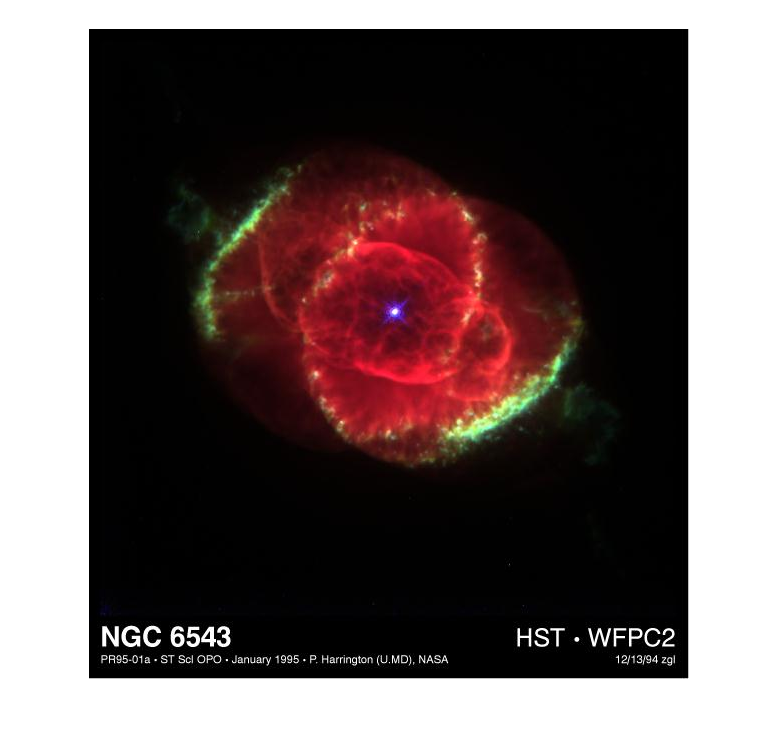

output=myFunction("ngc6543a.jpg");

function output=myFunction(input)
% input is the name of the image you want to input, e.g. "ngc6543a.jpg"
Image = imread(input);
figure, imshow(Image)
Image=double(Image);
output = mean(Image,3);
end